# Monocular Visual Simultaneous Localization and Mapping

Visual simultaneous localization and mapping (vSLAM), refers to the process of calculating the position and orientation of a camera with respect to its surroundings, while simultaneously mapping the environment. The process uses only visual inputs from the camera. Applications for vSLAM include augmented reality, robotics, and autonomous driving.

This example shows how to process image data from a monocular camera to build a map of an indoor environment and estimate the trajectory of the camera. The example uses ORB-SLAM [1], which is a feature-based vSLAM algorithm. 

To speed up computations, you can enable parallel computing from the[ Computer Vision Toolbox Preferences](docid:vision_gs#bugsb2y-1) dialog box. To open Computer Vision Toolbox™ preferences, on the **Home** tab, in the **Environment** section, click **Preferences**. Then select **Computer Vision Toolbox. **

## Glossary

The following terms are frequently used in this example:

- **Key Frames:** A subset of video frames that contain cues for localization and tracking. Two consecutive key frames usually involve sufficient visual change.

- **Map Points: **A list of 3-D points that represent the map of the environment reconstructed from the key frames.

- **Covisibility Graph**: A graph consisting of key frame as nodes. Two key frames are connected by an edge if they share common map points. The weight of an edge is the number of shared map points.

- **Essential Graph:** A subgraph of covisibility graph containing only edges with high weight, i.e. more shared map points.

- **Recognition Database: **A database used to recognize whether a place has been visited in the past. The database stores the visual word-to-image mapping based on the input bag of features. It is used to search for an image that is visually similar to a query image. 

## Overview of ORB-SLAM

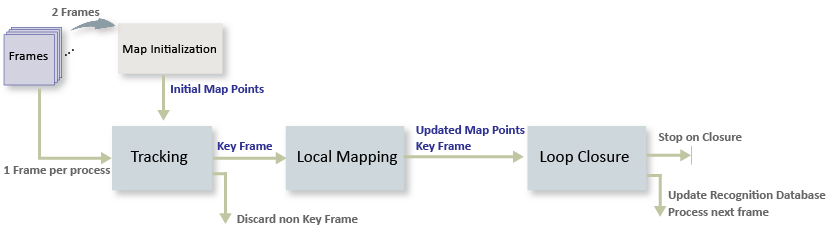

The ORB-SLAM pipeline includes:

- **Map Initialization**: ORB-SLAM starts by initializing the map of 3-D points from two video frames. The 3-D points and relative camera pose are computed using triangulation based on 2-D ORB feature correspondences. 

- **Tracking**: Once a map is initialized, for each new frame, the camera pose is estimated by matching features in the current frame to features in the last key frame. The estimated camera pose is refined by tracking the local map.

- **Local Mapping**: The current frame is used to create new 3-D map points if it is identified as a key frame. At this stage, bundle adjustment is used to minimize reprojection errors by adjusting the camera pose and 3-D points.  

- **Loop Closure**: Loops are detected for each key frame by comparing it against all previous key frames using the bag-of-features approach. Once a loop closure is detected, the pose graph is optimized to refine the camera poses of all the key frames.

## Download and Explore the Input Image Sequence

The data used in this example are from the [TUM RGB-D benchmark](https://vision.in.tum.de/data/datasets/rgbd-dataset) [2]. You can download the data to a temporary directory using a web browser or by running the following code:

baseDownloadURL = 'https://vision.in.tum.de/rgbd/dataset/freiburg3/rgbd_dataset_freiburg3_long_office_household.tgz'; 
dataFolder      = fullfile(tempdir, 'tum_rgbd_dataset', filesep); 
options         = weboptions('Timeout', Inf);
tgzFileName     = [dataFolder, 'fr3_office.tgz'];
folderExists    = exist(dataFolder, 'dir');

% Create a folder in a temporary directory to save the downloaded file
if ~folderExists  
    mkdir(dataFolder); 
    disp('Downloading fr3_office.tgz (1.38 GB). This download can take a few minutes.') 
    websave(tgzFileName, baseDownloadURL, options); 
    
    % Extract contents of the downloaded file
    disp('Extracting fr3_office.tgz (1.38 GB) ...') 
    untar(tgzFileName, dataFolder); 
end

Create an [`imageDatastore`](docid:matlab_ref#butueui-1) object to inspect the RGB images.

cam = ipcam('http://192.168.29.34:8080/video');

imageFolder   = strcat(pwd,'\..\imgseq\');
imds          = imageDatastore(imageFolder);
addpath('C:\Users\HP\Documents\MATLAB\Examples\R2020a\vision\MonocularVisualSimultaneousLocalizationAndMappingExample');
% Inspect the first image
currFrameIdx = 1;
input('enter');
currI = snapshot(cam);
himage = imshow(currI);

## **Map Initialization**

The ORB-SLAM pipeline starts by initializing the map that holds 3-D world points. This step is crucial and has a significant impact on the accuracy of final SLAM result. Initial ORB feature point correspondences are found using [`matchFeatures`](docid:vision_ref#bsvbhh1-1) between a pair of images. After the correspondences are found, two geometric transformation models are used to establish map initialization:

- **Homography**: If the scene is planar, a homography projective transformation is a better choice to describe feature point correspondences. 

- **Fundamental Matrix:** If the scene is non-planar, a fundamental matrix must be used instead.

The homography and the fundamental matrix can be computed using [`estimateGeometricTransform`](docid:vision_ref#btrzgde) and [`estimateFundamentalMatrix`](docid:vision_ref#bsjglej), respectively. The model that results in a smaller reprojection error is selected to estimate the relative rotation and translation between the two frames using [`relativeCameraPose`](docid:vision_ref#bvb_0da-1). Since the RGB images are taken by a monocular camera which does not provide the depth information, the relative translation can only be recovered up to a specific scale factor.    

Given the relative camera pose and the matched feature points in the two images, the 3-D locations of the matched points are determined using [`triangulate`](docid:vision_ref#buefm11-1) function. A triangulated map point is valid when it is located in the front of both cameras, when its reprojection error is low, and when the parallax of the two views of the point is sufficiently large.

% Set random seed for reproducibility
rng(0);

% Create a cameraIntrinsics object to store the camera intrinsic parameters.
% The intrinsics for the dataset can be found at the following page:
% https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
% Note that the images in the dataset are already undistorted, hence there
% is no need to specify the distortion coefficients.
focalLength    = [535.4, 539.2];    % in units of pixels
principalPoint = [320.1, 247.6];    % in units of pixels
imageSize      = size(currI,[1 2]);  % in units of pixels
intrinsics     = cameraIntrinsics(focalLength, principalPoint, imageSize);


calibrationData = load(strcat(pwd,'/../camera_params_camvid_g5.mat'));
input('enter');
I=snapshot(cam);

% Describe camera configuration.
focalLength    = calibrationData.cameraParams.FocalLength;
principalPoint = calibrationData.cameraParams.PrincipalPoint;
imageSize      = calibrationData.cameraParams.ImageSize;
intrinsics = cameraIntrinsics(focalLength, principalPoint, imageSize);



% Detect and extract ORB features
[preFeatures, prePoints] = helperDetectAndExtractFeatures(currI); 

currFrameIdx = currFrameIdx + 1;
firstI       = currI; % Preserve the first frame 

isMapInitialized  = false;

% Map initialization loop
while ~isMapInitialized
    currI = snapshot(cam);

    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI); 
    
    currFrameIdx = currFrameIdx + 1;
    
    % Find putative feature matches
    indexPairs = matchFeatures(preFeatures, currFeatures, 'Unique', true, ...
        'MaxRatio', 0.7, 'MatchThreshold', 70);
    
    % If not enough matches are found, check the next frame
    minMatches = 100;
    if size(indexPairs, 1) < minMatches
        continue
    end
    
    preMatchedPoints  = prePoints(indexPairs(:,1),:);
    currMatchedPoints = currPoints(indexPairs(:,2),:);
    
    % Compute homography and evaluate reconstruction
    [tformH, scoreH, inliersIdxH] = helperComputeHomography(preMatchedPoints, currMatchedPoints);

    % Compute fundamental matrix and evaluate reconstruction
    [tformF, scoreF, inliersIdxF] = helperComputeFundamentalMatrix(preMatchedPoints, currMatchedPoints);
    
    % Select the model based on a heuristic
    ratio = scoreH/(scoreH + scoreF);
    ratioThreshold = 0.45;
    if ratio > ratioThreshold
        inlierTformIdx = inliersIdxH;
        tform          = tformH;
    else
        inlierTformIdx = inliersIdxF;
        tform          = tformF;
    end

    % Computes the camera location up to scale. Use half of the 
    % points to reduce computation
    inlierPrePoints  = preMatchedPoints(inlierTformIdx);
    inlierCurrPoints = currMatchedPoints(inlierTformIdx);
    [relOrient, relLoc, validFraction] = relativeCameraPose(tform, intrinsics, ...
        inlierPrePoints(1:2:end), inlierCurrPoints(1:2:end));
    
    % If not enough inliers are found, move to the next frame
    if validFraction < 0.7 || numel(size(relOrient))==3
        continue
    end
    
    % Triangulate two views to obtain 3-D map points
    relPose = rigid3d(relOrient, relLoc);
    [isValid, xyzWorldPoints, inlierTriangulationIdx] = helperTriangulateTwoFrames(...
        rigid3d, relPose, inlierPrePoints, inlierCurrPoints, intrinsics);
    
    if ~isValid
        continue
    end
    
    % Get the original index of features in the two key frames
    indexPairs = indexPairs(inlierTformIdx(inlierTriangulationIdx),:);
    
    isMapInitialized = true;
    
    disp(['Map initialized with frame 1 and frame ', num2str(currFrameIdx-1)])
end % End of map initialization loop

Map initialized with frame 1 and frame 6


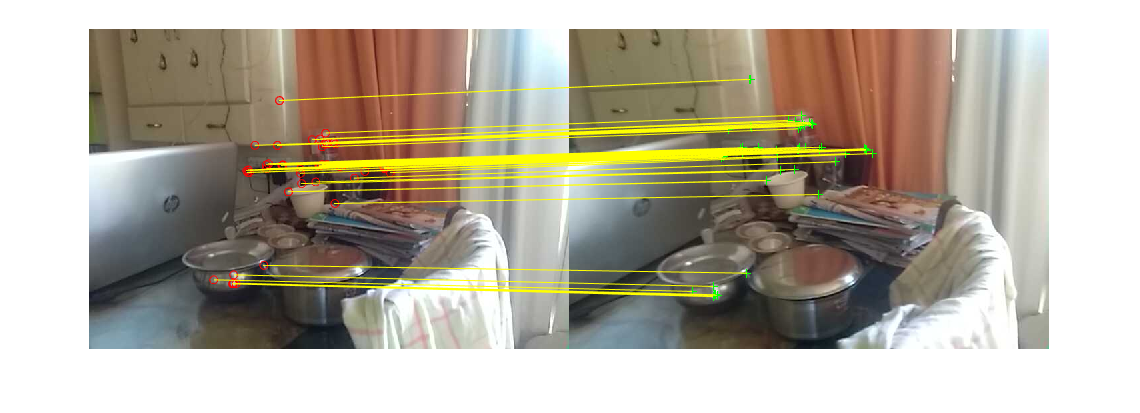


if isMapInitialized
    close(himage.Parent.Parent); % Close the previous figure
    % Show matched features
    hfeature = showMatchedFeatures(firstI, currI, prePoints(indexPairs(:,1)), ...
        currPoints(indexPairs(:, 2)), 'Montage');
    realDist=input('enter real world distance');
else
    error('Unable to initialize map.')
end

## Store Initial Key Frames and Map Points

After the map is initialized using two frames, you can use [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) and [`helperMapPointSet`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperMapPointSet.m')) to store the two key frames and the corresponding map points:

- [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) stores the key frames and their attributes, such as ORB descriptors, feature points and camera poses, and connections between the key frames, such as feature points matches and relative camera poses. The pose of the camera is stored as a [`rigid3d`](docid:vision_ref#mw_4ce2ed95-d8fe-46db-badc-926ffa42e1d1) object.

- [`helperMapPointSet`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperMapPointSet.m')) stores the map points and their attributes, such as 3-D positions, view directions, representative ORB descriptors, and the range of distance at which the map point can be observed. The map points object also stores the 3-D into 2-D projection correspondences: which map points are observed in a key frame and which key frames observe a map point.

% Create an empty imageviewset object to store key frames
vSetKeyFrames = imageviewset;

% Create an empty helperMapPointSet object to store 3D map points
mapPointSet   = helperMapPointSet;

% Add the first key frame. Place the camera associated with the first 
% key frame at the origin, oriented along the Z-axis
preViewId     = 1;
vSetKeyFrames = addView(vSetKeyFrames, preViewId, rigid3d, 'Points', prePoints,...
    'Features', preFeatures.Features);

% Add the second key frame
currViewId    = 2;
vSetKeyFrames = addView(vSetKeyFrames, currViewId, relPose, 'Points', currPoints,...
    'Features', currFeatures.Features);

% Add connection between the first and the second key frame
vSetKeyFrames = addConnection(vSetKeyFrames, preViewId, currViewId, relPose, 'Matches', indexPairs);

% Add 3-D map points
[mapPointSet, newPointIdx] = addMapPoint(mapPointSet, xyzWorldPoints);

% Add observations of the map points
preLocations   = prePoints.Location;
currLocations  = currPoints.Location;
preScales      = prePoints.Scale;
currScales     = currPoints.Scale;

% Add image points corresponding to the map points in the first key frame
mapPointSet   = addObservation(mapPointSet, newPointIdx, preViewId, indexPairs(:,1), ....
    preLocations(indexPairs(:,1),:), preScales(indexPairs(:,1)));

% Add image points corresponding to the map points in the second key frame
mapPointSet   = addObservation(mapPointSet, newPointIdx, currViewId, indexPairs(:,2), ...
    currLocations(indexPairs(:,2),:), currScales(indexPairs(:,2)));

## Refine and Visualize the Initial Reconstruction

Refine the initial reconstruction using [`bundleAdjustment`](docid:vision_ref#bu48f97-1), that optimizes both camera poses and world points to minimize the overall reprojection errors. After the refinement, the attributes of the map points including 3-D locations, view direction, and depth range are updated and stored in `mapPointSet`. You can use [`helperVisualizeMotionAndStructure`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMotionAndStructure.m')) to visualize the map points and the camera locations. 

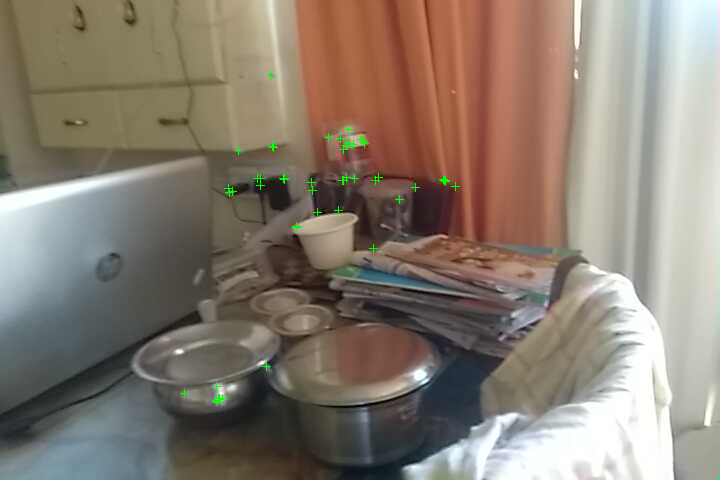

% Run full bundle adjustment on the first two key frames
tracks       = findTracks(vSetKeyFrames);
cameraPoses  = poses(vSetKeyFrames);

[refinedPoints, refinedAbsPoses] = bundleAdjustment(xyzWorldPoints, tracks, ...
    cameraPoses, intrinsics, 'FixedViewIDs', 1, ...
    'PointsUndistorted', true, 'AbsoluteTolerance', 1e-7,...
    'RelativeTolerance', 1e-15, 'MaxIteration', 50);

% Scale the map and the camera pose using the median depth of map points
medianDepth   = median(vecnorm(refinedPoints.'));
refinedPoints = refinedPoints / medianDepth;

refinedAbsPoses.AbsolutePose(currViewId).Translation = ...
    refinedAbsPoses.AbsolutePose(currViewId).Translation / medianDepth;
relPose.Translation = relPose.Translation/medianDepth;

% Update key frames with the refined poses
vSetKeyFrames = updateView(vSetKeyFrames, refinedAbsPoses);
vSetKeyFrames = updateConnection(vSetKeyFrames, preViewId, currViewId, relPose);

% Update map points with the refined positions
mapPointSet = updateLocation(mapPointSet, refinedPoints);

% Update view direction and depth 
mapPointSet = updateViewAndRange(mapPointSet, vSetKeyFrames.Views, newPointIdx);

% Visualize matched features in the current frame
close(hfeature.Parent.Parent);
featurePlot = helperVisualizeMatchedFeatures(currI, currPoints(indexPairs(:,2)));

% Visualize initial map points and camera trajectory
mapPlot     = helperVisualizeMotionAndStructure(vSetKeyFrames, mapPointSet);

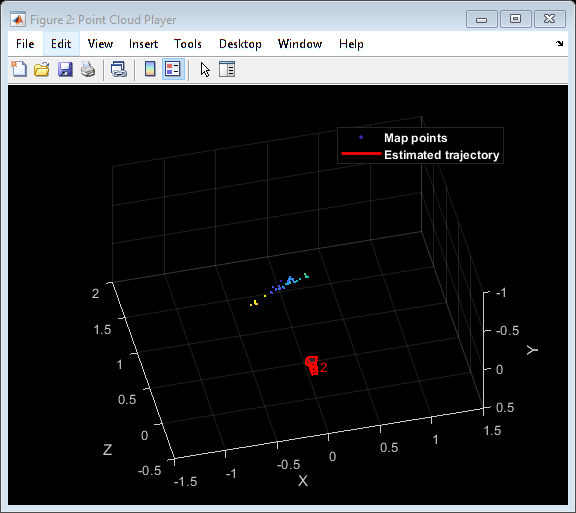


% Show legend
showLegend(mapPlot);

## Tracking

The tracking process is performed using every frame and determines when to insert a new key frame. To simplify this example, we will terminate the tracking process once a loop closure is found.

% ViewId of the current key frame
currKeyFrameId    = currViewId;

% ViewId of the last key frame
lastKeyFrameId    = currViewId;

% ViewId of the reference key frame that has the most co-visible 
% map points with the current key frame
refKeyFrameId     = currViewId;

% Index of the last key frame in the input image sequence
lastKeyFrameIdx   = currFrameIdx - 1; 

% Indices of all the key frames in the input image sequence
addedFramesIdx    = [1; lastKeyFrameIdx];

isLoopClosed      = false;

Each frame is processed as follows:

- ORB features are extracted for each new frame and then matched (using [`matchFeatures`](docid:vision_ref#bsvbhh1-1)), with features in the last key frame that have known corresponding 3-D map points. 

- Estimate the camera pose with the Perspective-n-Point algorithm using [`estimateWorldCameraPose`](docid:vision_ref#bvcns9r-1).

- Given the camera pose, project the map points observed by the last key frame into the current frame and search for feature correspondences using  [`helperMatchFeaturesInRadius`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperMatchFeaturesInRadius.m'))`. `

- With 3-D to 2-D correspondence in the current frame, refine the camera pose by performing a motion-only bundle adjustment using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf). 

- Project the local map points into the current frame to search for more feature correspondences using [`helperMatchFeaturesInRadius`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperMatchFeaturesInRadius.m')) and refine the camera pose again using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf). 

- The last step of tracking is to decide if the current frame is a new key frame. If the current frame is a key frame, continue to the **Local Mapping **process. Otherwise, start **Tracking** for the next frame.

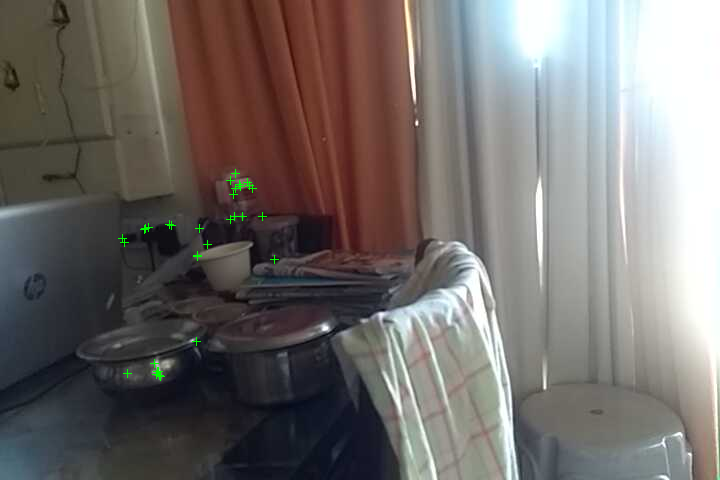

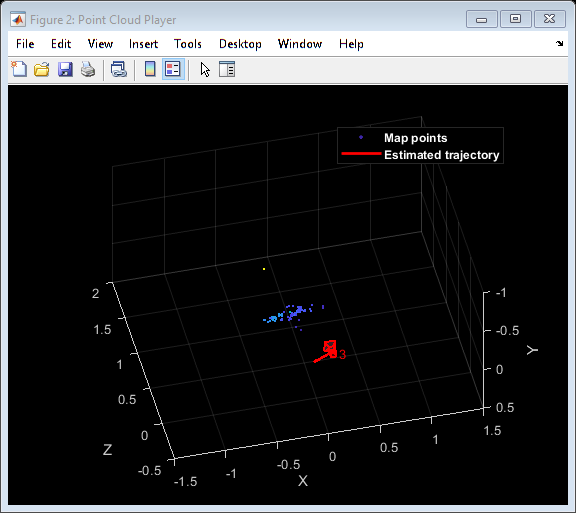

Error using imwrite (line 541)
Unable to open file ".png" for writing.  You might not have write permission.

% Main loop
while ~isLoopClosed
    currI = snapshot(cam);
    

    [currFeatures, currPoints] = helperDetectAndExtractFeatures(currI);

    % Track the last key frame
    % mapPointsIdx:   Indices of the map points observed in the current frame
    % featureIdx:     Indices of the corresponding feature points in the 
    %                 current frame
    [currPose, mapPointsIdx, featureIdx] = helperTrackLastKeyFrame(mapPointSet, ...
        vSetKeyFrames.Views, currFeatures, currPoints, lastKeyFrameId, intrinsics);
    
    % Track the local map
    % refKeyFrameId:      ViewId of the reference key frame that has the most 
    %                     co-visible map points with the current frame
    % localKeyFrameIds:   ViewId of the connected key frames of the current frame
    [refKeyFrameId, localKeyFrameIds, currPose, mapPointsIdx, featureIdx] = ...
        helperTrackLocalMap(mapPointSet, vSetKeyFrames, mapPointsIdx, ...
        featureIdx, currPose, currFeatures, currPoints, intrinsics);
    
    % Check if the current frame is a key frame. 
    % A frame is a key frame if both of the following conditions are satisfied:
    %
    % 1. At least 20 frames have passed since the last key frame or the 
    %    current frame tracks fewer than 80 map points
    % 2. The map points tracked by the current frame are fewer than 90% of 
    %    points tracked by the reference key frame
    isKeyFrame = helperIsKeyFrame(mapPointSet, refKeyFrameId, lastKeyFrameIdx, ...
        currFrameIdx, mapPointsIdx);
    
    % Visualize matched features
    updatePlot(featurePlot, currI, currPoints(featureIdx));
    
    if ~isKeyFrame
        currFrameIdx = currFrameIdx + 1;
        continue
    end
    
    % Update current key frame ID
    currKeyFrameId  = currKeyFrameId + 1;

## Local Mapping

Local mapping is performed for every key frame. When a new key frame is determined, add it to the key frames and update the attributes of the map points observed by the new key frame. To ensure that `mapPointSet` contains as few outliers as possible, a valid map point must be observed in at least 3 key frames. 

New map points are created by triangulating ORB feature points in the current key frame and its connected key frames. For each unmatched feature point in the current key frame, search for a match with other unmatched points in the connected key frames using [`matchFeatures`](docid:vision_ref#bsvbhh1-1). The local bundle adjustment refines the pose of the current key frame, the poses of connected key frames, and all the map points observed in these key frames.

    % Add the new key frame 
    [mapPointSet, vSetKeyFrames] = helperAddNewKeyFrame(mapPointSet, vSetKeyFrames, ...
        currPose, currFeatures, currPoints, mapPointsIdx, featureIdx, localKeyFrameIds);
    
    % Update view direction and depth
    mapPointSet = updateViewAndRange(mapPointSet, vSetKeyFrames.Views, mapPointsIdx);
    
    % Remove outlier map points that are observed in fewer than 3 key frames
    mapPointSet = helperCullRecentMapPoints(mapPointSet, vSetKeyFrames, newPointIdx);
    
    % Create new map points by triangulation
    [mapPointSet, vSetKeyFrames, newPointIdx] = helperCreateNewMapPoints(mapPointSet, vSetKeyFrames, ...
        currKeyFrameId, intrinsics);

    % Local bundle adjustment
    [mapPointSet, vSetKeyFrames] = helperLocalBundleAdjustment(mapPointSet, vSetKeyFrames, ...
        currKeyFrameId, intrinsics); 
    
    % Visualize 3D world points and camera trajectory
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

## Loop Closure

The loop closure step takes the current key frame processed by the local mapping process and tries to detect and close the loop. Loop detection is performed using the bags-of-words approach. A visual vocabulary represented as a [`bagOfFeatures`](docid:vision_ref#bufbdd6) object is created offline with the SURF descriptors extracted from a large set of images in the dataset by calling:

`bag = bagOfFeatures(imds,'CustomExtractor', @helperSURFFeatureExtractorFunction);`

where `imds` is an [`imageDatastore`](docid:matlab_ref#butueui-1) object storing the training images and [`helperSURFFeatureExtractorFunction`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperExtractorFunction.m')) is the SURF feature extractor function. See [Image Retrieval with Bag of Visual Words](docid:vision_ug#bun8icv-1) for more information.

The loop closure process incrementally builds a database, represented as an [`invertedImageIndex`](docid:vision_ref#bumxjai-1) object, that stores the visual word-to-image mapping based on the bag of SURF features. Loop candidates are identified by querying images in the database that are visually similar to the current key frame using [`evaluateImageRetrieval`](docid:vision_ref#bumxi3p-1). A candidate key frame is valid if it is not connected to the last key frame and three of its neighbor key frames are loop candidates. 

When a valid loop candidate is found, compute the relative pose between the loop candidate frame and the current key frame using the same strategy as the one used in the **Tracking** process. Then add the loop connection with the relative pose and update `mapPointSet `and `vSetKeyFrames`.

    % Initialize the loop closure database
    if currKeyFrameId == 3
        % Load the bag of features data created offline
        bofData         = load('bagOfFeaturesData.mat');
        loopDatabase    = invertedImageIndex(bofData.bof);
        loopCandidates  = [1; 2];
        
    % Check loop closure after some key frames have been created    
    elseif currKeyFrameId > 20
        
        % Detect possible loop closure key frame candidates
        [isDetected, validLoopCandidates] = helperCheckLoopClosure(vSetKeyFrames, currKeyFrameId, ...
            loopDatabase, currI, loopCandidates);
        
        if isDetected 
            % Add loop closure connections
            [isLoopClosed, mapPointSet, vSetKeyFrames] = helperAddLoopConnections(...
                mapPointSet, vSetKeyFrames, validLoopCandidates, ...
                currKeyFrameId, currFeatures, currPoints, intrinsics);
        end
    end
    
    % If no loop closure is detected, add the image into the database
    if ~isLoopClosed
        flname=strcat(string(currFrameIdx),'.png');
        imwrite(I,flname);
        currds = imageDatastore(flname);
        addImages(loopDatabase, currds, 'Verbose', false);
        loopCandidates= [loopCandidates; currKeyFrameId]; %#ok<AGROW>
    end
    
    % Update IDs and indices
    lastKeyFrameId  = currKeyFrameId;
    lastKeyFrameIdx = currFrameIdx;
    addedFramesIdx  = [addedFramesIdx; currFrameIdx]; %#ok<AGROW>
    currFrameIdx  = currFrameIdx + 1;
end % End of main loop

Finally, a pose graph optimization is performed over the essential graph in `vSetKeyFrames `to correct the drift in rotation and translation. The essential graph is created internally by removing connections with fewer than `minNumMatches `matches in the covisibility graph.

% Optimize the poses
minNumMatches      = 40;
vSetKeyFramesOptim = optimizePoses(vSetKeyFrames, minNumMatches, 'Tolerance', 1e-16, 'Verbose', true);

% Plot the optimized camera trajectory
optimizedPoses  = poses(vSetKeyFramesOptim);
plotOptimizedTrajectory(mapPlot, optimizedPoses)

% Update legend
showLegend(mapPlot);

## Compare with the Ground Truth

You can compare the optimized camera trajectory with the ground truth to evaluate the accuracy of ORB-SLAM. The downloaded data contains a `groundtruth.txt` file that stores the ground truth of camera pose of each frame. The data has been saved in the form of a MAT-file. You can also calculate the root-mean-square-error (RMSE) of trajectory estimates. 

% Load ground truth 
gTruthData = load('orbslamGroundTruth.mat');
gTruth     = gTruthData.gTruth;

% Plot the actual camera trajectory 
plotActualTrajectory(mapPlot, gTruth(addedFramesIdx), optimizedPoses);

% Show legend
showLegend(mapPlot);

% Evaluate tracking accuracy
helperEstimateTrajectoryError(gTruth(addedFramesIdx), optimizedPoses);

This concludes an overview of how to build a map of an indoor environment and estimate the trajectory of the camera using ORB-SLAM.

## Supporting Functions

Short helper functions are included below. Larger function are included in separate files.

[`helperAddLoopConnections`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperAddLoopConnections.m')) add connections between the current keyframe and the valid loop candidate.

[`helperAddNewKeyFrame`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperAddNewKeyFrame.m')) add key frames to the key frame set.

[`helperCheckLoopClosure`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperCheckLoopClosure.m')) detect loop candidates key frames by retrieving visually similar images from the database.

[`helperCreateNewMapPoints`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperCreateNewMapPoints.m')) create new map points by triangulation.

[`helperFindProjectedPointsInImage`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperFindProjectedPointsInImage.m')) check if projected world points are within an image.

[`helperHammingDistance`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperHammingDistance.m')) compute hamming distance between two groups of binary feature vectors.

[`helperLocalBundleAdjustment`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperLocalBundleAdjustment.m')) refine the pose of the current key frame and the map of the surrrounding scene.

[`helperMapPointSet`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperMapPointSet.m')) manage map data for visual SLAM.

[`helperMatchFeaturesInRadius`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperMatchFeaturesInRadius.m')) match features within a radius. 

[`helperSelectStrongConnections`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperSelectStrongConnections.m')) select strong connections with more than a specified number of matches.

[`helperSURFFeatureExtractorFunction`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperSURFFeatureExtractorFunction.m')) implements the SURF feature extraction used in bagOfFeatures.

[`helperTrackLastKeyFrame`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperTrackLastKeyFrame.m')) estimate the current camera pose by tracking the last key frame.

[`helperTrackLocalMap`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperTrackLocalMap.m')) refine the current camera pose by tracking the local map.

[`helperVisualizeMatchedFeatures`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMatchedFeatures.m')) show the matched features in a frame.

[`helperVisualizeMotionAndStructure`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperVisualizeMotionAndStructure.m')) show map points and camera trajectory.

`helperDetectAndExtractFeatures` detect and extract and ORB features from the image.

function [features, validPoints] = helperDetectAndExtractFeatures(Irgb, varargin)

scaleFactor = 1.2;
numLevels   = 8;
numPoints   = 1000;

% In this example, the images are already undistorted. In a general
% workflow, uncomment the following code to undistort the images.
%
% if nargin > 1
%     intrinsics = varargin{1};
% end
% Irgb  = undistortImage(Irgb, intrinsics);

% Detect ORB features
Igray  = rgb2gray(Irgb);

points = detectORBFeatures(Igray, 'ScaleFactor', scaleFactor, 'NumLevels', numLevels);

% Select a subset of features, uniformly distributed throughout the image
points = selectUniform(points, numPoints, size(Igray, 1:2));

% Extract features
[features, validPoints] = extractFeatures(Igray, points);
end

`helperHomographyScore `compute homography and evaluate reconstruction.

function [H, score, inliersIndex] = helperComputeHomography(matchedPoints1, matchedPoints2)

[H, inlierPoints1, inlierPoints2] = estimateGeometricTransform( ...
    matchedPoints1, matchedPoints2, 'projective', ...
    'MaxNumTrials', 1e3, 'MaxDistance', 4, 'Confidence', 90);

[~, inliersIndex] = intersect(matchedPoints1.Location, ...
    inlierPoints1.Location, 'row', 'stable');

locations1 = inlierPoints1.Location;
locations2 = inlierPoints2.Location;
xy1In2     = transformPointsForward(H, locations1);
xy2In1     = transformPointsInverse(H, locations2);
error1in2  = sum((locations2 - xy1In2).^2, 2);
error2in1  = sum((locations1 - xy2In1).^2, 2);

outlierThreshold = 6;

score = sum(max(outlierThreshold-error1in2, 0)) + ...
    sum(max(outlierThreshold-error2in1, 0));
end

 `helperFundamentalMatrixScore `compute fundamental matrix and evaluate reconstruction.

function [F, score, inliersIndex] = helperComputeFundamentalMatrix(matchedPoints1, matchedPoints2)

[F, inliersLogicalIndex]   = estimateFundamentalMatrix( ...
    matchedPoints1, matchedPoints2, 'Method','RANSAC',...
    'NumTrials', 1e3, 'DistanceThreshold', 0.01);

inlierPoints1 = matchedPoints1(inliersLogicalIndex);
inlierPoints2 = matchedPoints2(inliersLogicalIndex);

inliersIndex  = find(inliersLogicalIndex);

locations1    = inlierPoints1.Location;
locations2    = inlierPoints2.Location;

% Distance from points to epipolar line
lineIn1   = epipolarLine(F', locations2);
error2in1 = (sum([locations1, ones(size(locations1, 1),1)].* lineIn1, 2)).^2 ...
    ./ sum(lineIn1(:,1:2).^2, 2);
lineIn2   = epipolarLine(F, locations1);
error1in2 = (sum([locations2, ones(size(locations2, 1),1)].* lineIn2, 2)).^2 ...
    ./ sum(lineIn2(:,1:2).^2, 2);

outlierThreshold = 4;

score = sum(max(outlierThreshold-error1in2, 0)) + ...
    sum(max(outlierThreshold-error2in1, 0));

end

`helperTriangulateTwoFrames `triangulate two frames to initialize the map.

function [isValid, xyzPoints, inlierIdx] = helperTriangulateTwoFrames(...
    pose1, pose2, matchedPoints1, matchedPoints2, intrinsics)

[R1, t1]   = cameraPoseToExtrinsics(pose1.Rotation, pose1.Translation);
camMatrix1 = cameraMatrix(intrinsics, R1, t1);

[R2, t2]   = cameraPoseToExtrinsics(pose2.Rotation, pose2.Translation);
camMatrix2 = cameraMatrix(intrinsics, R2, t2);

[xyzPoints, reprojectionErrors] = triangulate(matchedPoints1, ...
    matchedPoints2, camMatrix1, camMatrix2);

% Filter points by view direction and reprojection error
minReprojError = 1;
inlierIdx  = xyzPoints(:,3) > 0 & reprojectionErrors < minReprojError;
xyzPoints  = xyzPoints(inlierIdx ,:);

% A good two-view with significant parallax
ray1       = xyzPoints - pose1.Translation;
ray2       = xyzPoints - pose2.Translation;
cosAngle   = sum(ray1 .* ray2, 2) ./ (vecnorm(ray1, 2, 2) .* vecnorm(ray2, 2, 2));

% Check parallax
minParallax = 3; % in degrees
isValid = all(cosAngle < cosd(minParallax) & cosAngle>0);
end

`helperIsKeyFrame `check if a frame is a key frame.

function isKeyFrame = helperIsKeyFrame(mapPoints, ...
    refKeyFrameId, lastKeyFrameIndex, currFrameIndex, mapPointsIndices)

numPointsRefKeyFrame = numel(getMapPointIndex(mapPoints, refKeyFrameId));

% More than 20 frames have passed from last key frame insertion
tooManyNonKeyFrames = currFrameIndex >= lastKeyFrameIndex + 20;

% Track less than 80 map points
tooFewMapPoints     = numel(mapPointsIndices) < 80;

% Tracked map points are fewer than 90% of points tracked by
% the reference key frame
tooFewTrackedPoints = numel(mapPointsIndices) < 0.9 * numPointsRefKeyFrame;

isKeyFrame = (tooManyNonKeyFrames || tooFewMapPoints) && tooFewTrackedPoints;
end

`helperCullRecentMapPoints `cull recently added map points.

function mapPoints = helperCullRecentMapPoints(mapPoints, keyFrames, newPointIdx)

for i = 1: numel(newPointIdx)
    idx =  newPointIdx(i);
    % If a map point is observed in less than 3 key frames, drop it
    if numel(mapPoints.Observations{idx, 1})< 3 &&...
            max(mapPoints.Observations{idx, 1}) < keyFrames.Views.ViewId(end)
        mapPoints = updateValidity(mapPoints, idx, false);
    end
end
end

`helperEstimateTrajectoryError`` calculate` the tracking error.

function rmse = helperEstimateTrajectoryError(gTruth, cameraPoses)
locations       = vertcat(cameraPoses.AbsolutePose.Translation);
gLocations      = vertcat(gTruth.Translation);
scale           = median(vecnorm(gLocations, 2, 2))/ median(vecnorm(locations, 2, 2));
scaledLocations = locations * scale;

rmse = sqrt(mean( sum((scaledLocations - gLocations).^2, 2) ));
disp(['Absolute RMSE for key frame trajectory (m): ', num2str(rmse)]);
end

## **Reference**

[1] Mur-Artal, Raul, Jose Maria Martinez Montiel, and Juan D. Tardos. "ORB-SLAM: a versatile and accurate monocular SLAM system." *IEEE Transactions on Robotics* 31, no. 5, pp 1147-116, 2015.

[2] Sturm, Jürgen, Nikolas Engelhard, Felix Endres, Wolfram Burgard, and Daniel Cremers. "A benchmark for the evaluation of RGB-D SLAM systems". In *Proceedings of IEEE/RSJ International Conference on Intelligent Robots and Systems*, pp. 573-580, 2012.

*Copyright 2019 The MathWorks, Inc.*